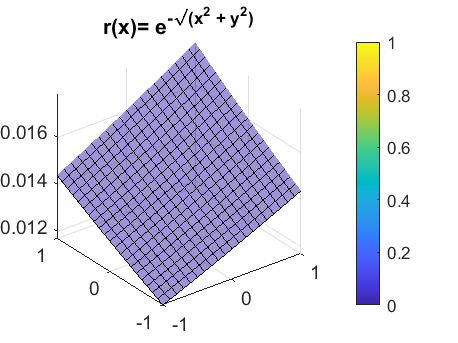

clc;
clear;

x = linspace(-1,1,300);
y = linspace(-1,1,300);

[X,Y] = meshgrid(x,y);
k = -log(0.05)/20;

Z = exp(-k*sqrt((X-20).^2 + (Y-20).^2));
figure
ex3D = surf(X,Y,Z);
    ex3D.EdgeColor = 'none';
    ex3D.FaceAlpha = 0.5;
hold on
spacing = 15;  % play around so it fits the size of your data set
for i = 1 : spacing : length(X(:,1))
    plot3(X(:,i), Y(:,i), Z(:,i),'-k');
    plot3(X(i,:), Y(i,:), Z(i,:),'-k');
end
colorbar
clim([0 1])
title('r(x)= e^{-\surd{(x^2 + y^2)}}');
saveas(ex3D,'Exp2.jpg')




kx = -log(0.1)/50

kx = 0.0461

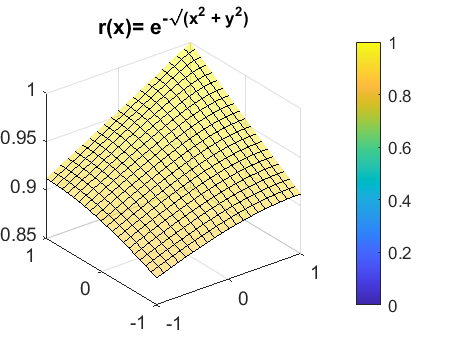


Z = exp(-kx*sqrt((X-1).^2 + (Y-1).^2));
figure
ex23D = surf(X,Y,Z);
    ex23D.EdgeColor = 'none';
    ex23D.FaceAlpha = 0.5;
hold on
spacing = 15;  % play around so it fits the size of your data set
for i = 1 : spacing : length(X(:,1))
    plot3(X(:,i), Y(:,i), Z(:,i),'-k');
    plot3(X(i,:), Y(i,:), Z(i,:),'-k');
end
colorbar
clim([0 1])
title('r(x)= e^{-\surd{(x^2 + y^2)}}');
saveas(ex23D,'Exp23.jpg')



Threshold = 0.1;
eff = 20

eff = 20

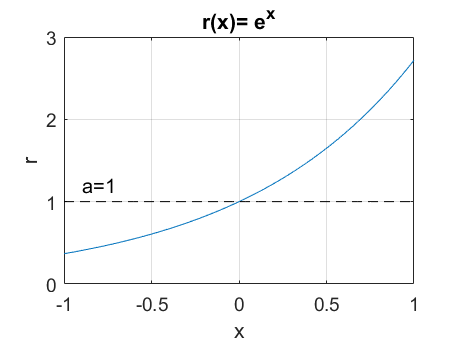

k1d = -log(Threshold)/eff;

r = exp(x);

ex = figure;
plot(x,r);
hold on

plot(x,ones(1,300),Color=[0 0 0],LineStyle="--")
text(-0.9,1.2,'a=1')

title('r(x)= e^{x}');

xlabel('x');
ylabel('r');
grid

saveas(ex,'Exp3.jpg')